% ROV Data
m = 10;             % Mass [kg]
Iyy = 0.766;
S = 0.15;         % reference area [m]
MAC = 0.5;        % Mean aerodynamic chord [m]
zb = 0.25;
zg = 0.2;
Cd0 = 0.07;
Cl = 0.015;
Cl_alpha = 0.0995;  % dCl/dalpha [rad^-1]
Cd_alpha = -0.0824; % dCd/dalpha [rad^-1]
Cm_alpha = 0.1592;  % dCm/dalpha [rad^-1]
Cm_q = -0.1455;     % dCm/dq [s.m^-1]
Fb = 10*9.81;

% Operating conditions
g = 9.81;           % Gravitational acceleration
rho = 997.99;       % Density [kg.m^-3]
V0 = 2;             % Steady state speed [m.s^-1]
alpha = 0;
theta = 0;

% Dimensional stability derivatives
Xu = -2*Cd0*0.5*rho*V0*S

Xu = -20.9578

Xw = (Cl-Cd_alpha)*0.5*rho*V0*S

Xw = 14.5806

Xq = 0 % no tail 

Xq = 0

Xq_dot = 0 % no tail 

Xq_dot = 0

Xw_dot = -3.563893

Xw_dot = -3.5639


Zu = -2*Cl*0.5*V0*S

Zu = -0.0045

Zw = (-Cd0-Cl_alpha)*0.5*rho*V0*S

Zw = -25.3739

Zq = 0 % no tail 

Zq = 0

Zq_dot = 0 % no tail 

Zq_dot = 0

Zw_dot = 0 % no tail 

Zw_dot = 0


Mu = 0 % no tail 

Mu = 0

Mw = Cm_alpha*(0.5*rho*V0*S*MAC)

Mw = 11.9160

Mq = Cm_q*0.5*rho*V0*S*MAC^2 % would be zero, but we do have pitch damping from the body

Mq = -5.4453

Mw_dot = 0 % No tail an no downwash lag

Mw_dot = 0


% Equations of motion
M = [m -Xw_dot 0 0;
    0 m-Zw_dot 0 0;
    0   -Mw_dot  Iyy 0;
    0 0 0 1];
A_prime = [Xu  Xw  Xq  -m*g;
     Zu Zw Zq+m*V0 0;
     -Mu -Mw Mq Fb*(zb-zg);
     0 0 1 0];
B_prime = [1; 0; 0.02; 0]

B_prime =     1.0000
         0
    0.0200
         0


A = m^-1*A_prime

A =    -2.0958    1.4581         0   -9.8100
   -0.0004   -2.5374    2.0000         0
         0   -1.1916   -0.5445    0.4905
         0         0    0.1000         0


B = M^-1*B_prime

B =     0.1000
         0
    0.0261
         0


C = [eye(4)];
D = 0;
% Linear time invariant system
ltisys = ss(A,B,C,D)

ltisys =
 
  A = 
             x1        x2        x3        x4
   x1    -2.096     1.458         0     -9.81
   x2  -0.00045    -2.537         2         0
   x3         0    -1.192   -0.5445    0.4905
   x4         0         0       0.1         0
 
  B = 
            u1
   x1      0.1
   x2        0
   x3  0.02611
   x4        0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



% Transfer function for u,w,q disturbance
sys = tf(ltisys)

sys =
 
  From input to output...
         0.1 s^3 + 0.3082 s^2 + 0.4221 s - 0.07744
   1:  ----------------------------------------------
       s^4 + 5.178 s^3 + 10.18 s^2 + 7.663 s - 0.2603
 
             0.05217 s^2 + 0.1094 s + 1.373e-05
   2:  ----------------------------------------------
       s^4 + 5.178 s^3 + 10.18 s^2 + 7.663 s - 0.2603
 
       0.02611 s^3 + 0.121 s^2 + 0.1389 s - 2.379e-19
   3:  ----------------------------------------------
       s^4 + 5.178 s^3 + 10.18 s^2 + 7.663 s - 0.2603
 
             0.002611 s^2 + 0.0121 s + 0.01389
   4:  ----------------------------------------------
       s^4 + 5.178 s^3 + 10.18 s^2 + 7.663 s - 0.2603
 
Continuous-time transfer function.


poles = pole(sys)

poles =   -2.0950 + 0.0000i
  -1.5576 + 1.1800i
  -1.5576 - 1.1800i
   0.0325 + 0.0000i


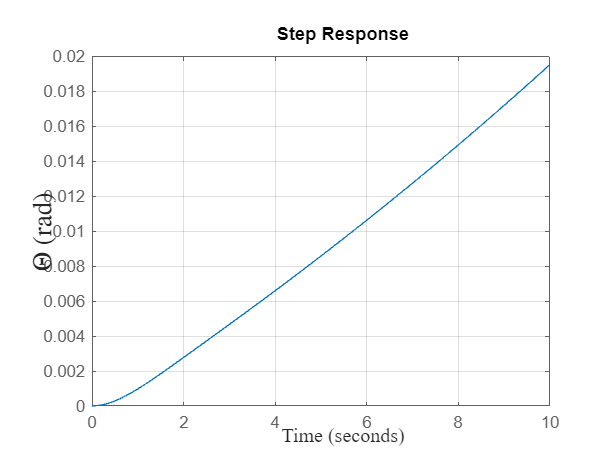

stepplot(sys(4,1),10)
xlabel("Time","FontSize",12,"FontName","Times New Romans"), ylabel("$\Theta$ (rad)", "Interpreter","latex","FontName","Times New Roman", "FontSize",16)
grid on

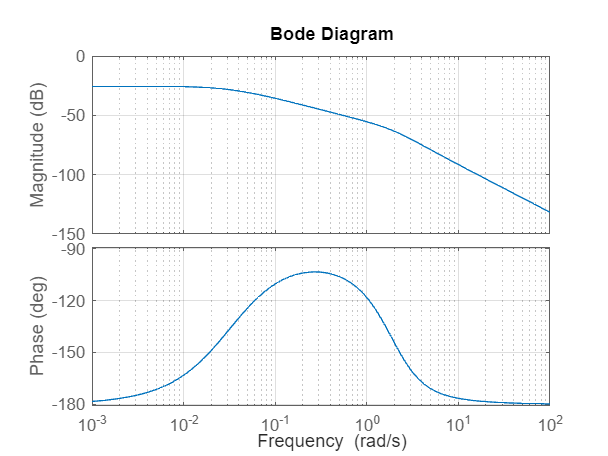

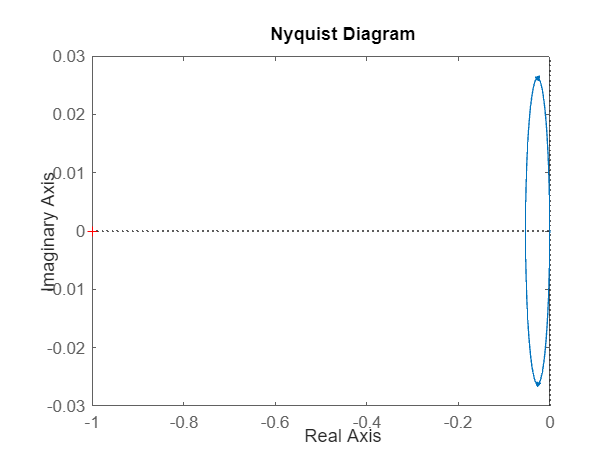


bode(sys(4,1))
grid on